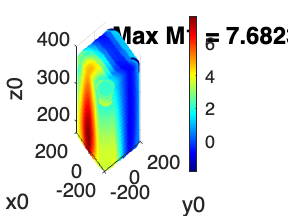

clc;
clear;

% Momentenberechnung

% Trigonometrische Konstanten
sqrt3 = sqrt(3.0);
pi = 3.141592653; 
cos30 = sqrt3/2;
cos60 = 0.5;
cos120 = -0.5;
tan30 = 1 / sqrt3;
tan60 = sqrt3;
sin30 = 0.5;
sin60 = sqrt3 / 2.0;
sin120 = sqrt3 / 2.0;

% Robotergeometrie
re = 35;                    % Radius des Endeffektors
e = 2 * re * tan60;
rf = 90;                     % Radius der Motorgrundplatte
f = 2 * rf * tan60;
le = 300.0;                 % Länge des Oberarms
lf = 200.0;                 % Länge des Unterarms

% Inverse Kinematik - Berechnung der Motorwinkel für vorgegebend Positon des Endeffektors

% Am Endeffektor wirkende Kräfte
Fx = 0;
Fy = 0;
Fz = 40;

function theta = delta_calcAngleYZ(x0, y0, z0, f, e, lf, le, tan30)
    y1 = -0.5 * tan30 * f;
    y0 = y0 - 0.5 * 0.57735 * e;
    a = (x0^2 + y0^2 + z0^2 + lf^2 - le^2 - y1^2) / (2 * -z0);
    b = (y1 - y0) / -z0;
    d = -(a + b * y1)^2 + lf * (b^2 * lf + lf); 
    if d < 0
        theta = NaN;
        return;
    end
    yj = (y1 - a * b - sqrt(d)) / (b^2 + 1);
    zj = a + b * yj;
    theta = 180.0 * atan(-zj / (y1 - yj)) / pi;
end

M1 = zeros(31,31,10);
M2 = zeros(31,31,10);
M3 = zeros(31,31,10);

i = 1;
j = 1;
k = 1;

for z0 = 170:10:370
    for x0 = -150:10:150
        for y0 = -150:10:150
    
            theta1 = delta_calcAngleYZ(x0, y0, z0, f, e, lf, le, tan30);
            theta2 = delta_calcAngleYZ(x0*cos120 + y0*sin120, y0*cos120-x0*sin120, z0, f, e, lf, le, tan30);
            theta3 = delta_calcAngleYZ(x0*cos120 - y0*sin120, y0*cos120+x0*sin120, z0, f, e, lf, le, tan30);
            
            % Berechnung der Winkel in der xy-Ebene zwischen Oberarm und endeffektor
            theta1 = theta1 * pi/180;
            %if theta1 < 0
            %    theta1 = pi + theta1;
            %end
            
            theta2 = theta2 * pi/180;
            %if theta2 < 0
            %    theta2 = pi + theta2;
            %end
            
            theta3 = theta3 * pi/180;
            %if theta3 < 0
            %    theta3 = pi + theta3;
            %end
            
            %disp(['theta1 = ', num2str(theta1 * 180/pi), ' deg']);
            %disp(['theta2 = ', num2str(theta2 * 180/pi), ' deg']);
            %disp(['theta3 = ', num2str(theta3 * 180/pi), ' deg']);
            
            A1B1 = [0; lf * cos(theta1); -lf * sin(theta1)];
            norm(A1B1); % Zur Überprüfung muss gleich lf sein
            
            A2B2 = [-lf * cos(theta2) * cos30; -lf * cos(theta2) * sin30; -lf * sin(theta2)];
            norm(A2B2); % Zur Überprüfung muss gleich lf sein
            
            A3B3 = [lf * cos(theta3) * cos30; -lf * cos(theta3) * sin30; -lf * sin(theta3)];
            norm(A3B3); % Zur Überprüfung muss gleich lf sein
            
            B1C1 = [x0;
                    y0 - re + rf + lf * cos(theta1);
                    z0 - lf * sin(theta1)];
            norm(B1C1); % Zur Überprüfung muss gleich le sein
            
            B2C2 = [x0 + re*cos30 - (rf + lf*cos(theta2)) * cos30;
                    y0 + re*sin30 - (rf + lf*cos(theta2)) * sin30;
                    z0 - lf * sin(theta2)];
            norm(B2C2); % Zur Überprüfung muss gleich le sein
            
            B3C3 = [x0 - re*cos30 - (-rf - lf*cos(theta3)) * cos30;
                    y0 + re*sin30 - (rf + lf*cos(theta3)) * sin30;
                    z0 - lf * sin(theta3)];
            norm(B3C3); % Zur Überprüfung muss gleich le sein
            
            % Winkelberechnung Draufsicht nur x und y Komponenten relevant
            A1B1xy = A1B1(1:2,1);
            A2B2xy = A2B2(1:2,1);
            A3B3xy = A3B3(1:2,1);
            
            B1C1xy = B1C1(1:2,1);
            B2C2xy = B2C2(1:2,1);
            B3C3xy = B3C3(1:2,1);
            
            alpha1 = acos(dot(A1B1xy,B1C1xy)/(norm(A1B1xy) * norm(B1C1xy)));
            alpha2 = acos(dot(A2B2xy,B2C2xy)/(norm(A2B2xy) * norm(B2C2xy)));
            alpha3 = acos(dot(A3B3xy,B3C3xy)/(norm(A3B3xy) * norm(B3C3xy)));
            
            alpha1 = real(alpha1);
            alpha2 = real(alpha2);
            alpha3 = real(alpha3);
            
            %disp(['alpha1 = ', num2str(alpha1 * 180/pi), ' deg']);
            %disp(['alpha2 = ', num2str(alpha2 * 180/pi), ' deg']);
            %disp(['alpha3 = ', num2str(alpha3 * 180/pi), ' deg']);
            
            % Winkelberechnung Frontansicht
            % Arm 1
            l1 = sin(theta1)*lf;
            l2 = cos(theta1)*lf;
            h1 = z0 - l1;
            l3 = l2 + rf - re + y0;
            beta1 = atan(l3/h1);
            %disp(['beta1 = ', num2str(beta1 * 180/pi), ' deg']);
            
            % Arm 2
            l1 = sin(theta2)*lf;
            l2 = cos(theta2)*lf;
            h1 = z0 - l1;
            deltaxy = cos30 * x0 + sin30 * y0;
            l3 = l2 + rf - re - deltaxy;
            beta2 = atan(l3/h1);
            %disp(['beta2 = ', num2str(beta2 * 180/pi), ' deg']);
            
            % Arm 3
            l1 = sin(theta3)*lf;
            l2 = cos(theta3)*lf;
            h1 = z0 - l1;
            deltaxy = -sin60 * x0 + cos60 * y0;
            l3 = l2 + rf - re - deltaxy;
            beta3 = atan(l3/h1);
            % disp(['beta3 = ', num2str(beta3 * 180/pi), ' deg']);
            
            % Kräftegleichgewicht
            
            B = [Fx;
                 Fy;
                 Fz];
            
            % Je nach Position des Endeffektors ergeben sich unterschiedliche Matrizen A
            
            if (x0 <= 0) && (y0 >= -x0 * tan30)
            
                A = [sin(beta1)*sin(alpha1),    sin(beta2)*sin(alpha2+pi/3),    -sin(beta3)*sin(alpha3+pi/3);
                     -sin(beta1)*cos(alpha1),   sin(beta2)*cos(alpha2+pi/3),    sin(beta3)*cos(alpha3+pi/3);
                     cos(beta1),                cos(beta2),                     cos(beta3)];
            
                F = mldivide(A, B);
            
            elseif (x0 >= 0) && (y0 >= x0 * tan30)
            
                A = [-sin(beta1)*sin(alpha1),   sin(beta2)*sin(alpha2+pi/3),    -sin(beta3)*sin(alpha3+pi/3);
                     -sin(beta1)*cos(alpha1),   sin(beta2)*cos(alpha2+pi/3),    sin(beta3)*cos(alpha3+pi/3);
                     cos(beta1),                cos(beta2),                     cos(beta3)];
            
                F = mldivide(A, B);
            
            elseif (x0 >= 0) && (y0 >= -x0 * tan30) && (y0 <= x0 * tan30)
            
                A = [-sin(beta1)*sin(alpha1),   sin(beta2)*sin(pi/3-alpha2),    -sin(beta3)*sin(alpha3+pi/3);
                     -sin(beta1)*cos(alpha1),   sin(beta2)*cos(pi/3-alpha2),    sin(beta3)*cos(alpha3+pi/3);
                     cos(beta1),                cos(beta2),                     cos(beta3)];
            
                F = mldivide(A, B);
            
            elseif (x0 >= 0) && (y0 <= -x0 * tan30)
            
                A = [-sin(beta1)*sin(alpha1),   sin(beta2)*sin(pi/3-alpha2),    -sin(beta3)*sin(pi/3-alpha3);
                     -sin(beta1)*cos(alpha1),   sin(beta2)*cos(pi/3-alpha2),    sin(beta3)*cos(pi/3-alpha3);
                     cos(beta1),                cos(beta2),                     cos(beta3)];
            
                F = mldivide(A, B);
            
            elseif (x0 <= 0) && (y0 <= x0 * tan30)
            
                A = [sin(beta1)*sin(alpha1),    sin(beta2)*sin(pi/3-alpha2),    -sin(beta3)*sin(pi/3-alpha3);
                     -sin(beta1)*cos(alpha1),   sin(beta2)*cos(pi/3-alpha2),    sin(beta3)*cos(pi/3-alpha3);
                     cos(beta1),                cos(beta2),                     cos(beta3)];
            
                F = mldivide(A, B);
            
            elseif (x0 <= 0) && (y0 >= x0 * tan30) && (y0 <= -x0 * tan30)
            
                A = [sin(beta1)*sin(alpha1),    sin(beta2)*sin(pi/3+alpha2),    -sin(beta3)*sin(pi/3-alpha3);
                     -sin(beta1)*cos(alpha1),   sin(beta2)*cos(pi/3+alpha2),    sin(beta3)*cos(pi/3-alpha3);
                     cos(beta1),                cos(beta2),                     cos(beta3)];
            
                F = mldivide(A, B);
            
            else
                % disp('Endeffektor liegt in keinem der 6 Felder')
            
            end
            
            %disp(['F1 = ', num2str(F(1)), ' N']);
            %disp(['F2 = ', num2str(F(2)), ' N']);
            %disp(['F3 = ', num2str(F(3)), ' N']);
            
            
            % Berechnung des wirkenden Momentes am Motor
            % (hier nur Motor 1 betrachtet - übrigen Motoren werden analog berechnet und führen zu dem selben Ergebniss)
            
            F1Z = F(1) * cos(alpha1);
            gamma1 = ((pi/2 - (pi/2 - beta1) - theta1)) * 180/pi;
            
            M1(i,j,k) = F(1) * cos(alpha1) * cos(beta1 + theta1) * lf / 1000;

            F2Z = F(2) * cos(alpha2);
            gamma2 = ((pi/2 - (pi/2 - beta2) - theta2)) * 180/pi;
            
            M2(i,j,k) = F(2) * cos(alpha2) * cos(beta2 + theta2) * lf / 1000;

            F3Z = F(3) * cos(alpha3);
            gamma3 = ((pi/2 - (pi/2 - beta3) - theta3)) * 180/pi;
            
            M3(i,j,k) = F(3) * cos(alpha3) * cos(beta3 + theta3) * lf / 1000;
            
            %disp(['M1 = ', num2str(M1), ' Nm' ]);
               
            j = j + 1;
        end
    
        j = 1;
        i = i + 1;
    end

    i = 1;
    k = k + 1;
end

% Erstellen des Gitters für X, Y und Z
[X, Y, Z] = meshgrid(-150:10:150, -150:10:150, 170:10:370);

% Umwandeln der Matrizen in Vektoren für scatter3
X = X(:);
Y = Y(:);
Z = Z(:);
M1 = M1(:); % M1 ebenfalls in Vektorform umwandeln
M2 = M2(:);
M3 = M3(:);

% Streudiagramm mit Farben basierend auf Werten in M1
figure(1)
scatter3(X, Y, Z, 50, M1, 'filled');
colormap(jet); % Farbskala
colorbar; % Farbskala anzeigen
xlabel('y0');
ylabel('x0');
zlabel('z0');

% Maximalen Wert von M1 berechnen
maxValue = max(M1);

% Maximalwert im Plot anzeigen
textPosition = [max(X) + 10, max(Y) + 10, max(Z)]; % Position außerhalb des Plots für bessere Lesbarkeit
text(textPosition(1), textPosition(2), textPosition(3), ['Max M1 = ', num2str(maxValue)], ...
    'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k', 'BackgroundColor', 'w');

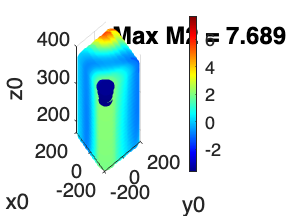


figure(2)
scatter3(X, Y, Z, 50, M2, 'filled');
colormap(jet); % Farbskala
colorbar; % Farbskala anzeigen
xlabel('y0');
ylabel('x0');
zlabel('z0');

% Maximalen Wert von M1 berechnen
maxValue = max(M2);

% Maximalwert im Plot anzeigen
textPosition = [max(X) + 10, max(Y) + 10, max(Z)]; % Position außerhalb des Plots für bessere Lesbarkeit
text(textPosition(1), textPosition(2), textPosition(3), ['Max M2 = ', num2str(maxValue)], ...
    'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k', 'BackgroundColor', 'w');

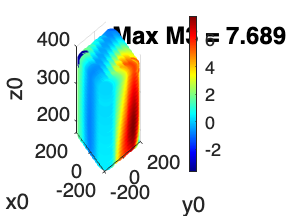


figure(3)
scatter3(X, Y, Z, 50, M3, 'filled');
colormap(jet); % Farbskala
colorbar; % Farbskala anzeigen
xlabel('y0');
ylabel('x0');
zlabel('z0');

% Maximalen Wert von M1 berechnen
maxValue = max(M2);

% Maximalwert im Plot anzeigen
textPosition = [max(X) + 10, max(Y) + 10, max(Z)]; % Position außerhalb des Plots für bessere Lesbarkeit
text(textPosition(1), textPosition(2), textPosition(3), ['Max M3 = ', num2str(maxValue)], ...
    'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k', 'BackgroundColor', 'w');